# Actividad 3.3

María José Croche Álvarez | A01734561

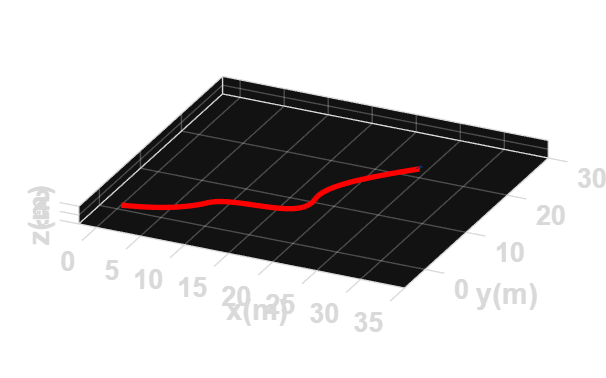

clear
close all
clc

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% TIEMPO %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

tf = 30;             
ts = 0.1;            
t = 0: ts: tf;       
N = length(t);       

%%%%%%%%%%%%%%%%%%%%%%%% CONDICIONES INICIALES %%%%%%%%%%%%%%%%%%%%%%%%%%%%

x1 = zeros(1,N+1);  
y1 = zeros(1,N+1);  
phi = zeros(1,N+1); 

x1(1) = 0;              
y1(1) = 1;              
phi(1) = atan(0.2);             

%%%%%%%%%%%%%%%%%%%%%%%%%%%% PUNTO DE CONTROL %%%%%%%%%%%%%%%%%%%%%%%%%%%%%

hx = zeros(1,N+1);  
hy = zeros(1,N+1);  

hx(1) = x1(1);
hy(1) = y1(1);

%%%%%%%%%%%%%%%%%%%%%% VELOCIDADES DE REFERENCIA %%%%%%%%%%%%%%%%%%%%%%%%%%

u = zeros(1,N); 
w = zeros(1,N); 

for k = 1:N
    
    tk = t(k);
    
    % -------- TRAMO 1 --------
    % % %Función y(t)=t2
    % t=[0 a 5]

    if tk <= 8
        
        dx = 1;
        dy = 0.2*exp(0.2*tk);
        
        u(k) = sqrt(dx^2 + dy^2);
        w(k) = (0.04*exp(0.2*tk)) / (1 + (0.2*exp(0.2))^2);
        
            
        % -------- TRAMO 2 --------
        %Función y(t)=sin(t)
        % t=[5 a 20]

    elseif tk <= 18
        
        dx = 1;
        dy = -1.2*sin(0.4*(tk - 8));
        
        u(k) = sqrt(dx^2 + dy^2);
        w(k) = (-0.48*cos(0.4*(tk-8))) / (1 + (-1.2*sin(0.4*(tk-8)))^2);
        
            
        % -------- TRAMO 3 --------
        %Función y(t)=0.5t+2
        % t=[20 a 30]
        
    else
        
        dx = 1;
        dy = 2 / (tk - 17);
        
        u(k) = sqrt(dx^2 + dy^2);
        w(k) = (-2 / (tk - 17)^2)/ (1 + (2 / (tk -17))^2);
        
    end
    
end

%%%%%%%%%%%%%%%%%%%%%%%%% BUCLE DE SIMULACION %%%%%%%%%%%%%%%%%%%%%%%%%%%%%

for k=1:N 
    
    phi(k+1)=phi(k)+w(k)*ts;
    
    xp1=u(k)*cos(phi(k+1)); 
    yp1=u(k)*sin(phi(k+1));

    x1(k+1)=x1(k) + xp1*ts; 
    y1(k+1)=y1(k) + yp1*ts; 
    
    hx(k+1)=x1(k+1); 
    hy(k+1)=y1(k+1);

end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%% SIMULACION 3D %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

scene=figure;
set(scene,'Color','white');
set(gca,'FontWeight','bold');
sizeScreen=get(0,'ScreenSize');
set(scene,'position',sizeScreen);
camlight('headlight');
axis equal;
grid on;
box on;
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)');

view([25 25]);
axis([-2 35 -5 30 0 2]);

scale = 4;
MobileRobot_5;
H1=MobilePlot_4(x1(1),y1(1),phi(1),scale);hold on;

H2=plot3(hx(1),hy(1),0,'r','lineWidth',2);

step=1;

for k=1:step:N

    delete(H1);    
    delete(H2);
    
    H1=MobilePlot_4(x1(k),y1(k),phi(k),scale);
    H2=plot3(hx(1:k),hy(1:k),zeros(1,k),'r','lineWidth',2);
    
    pause(ts);

end

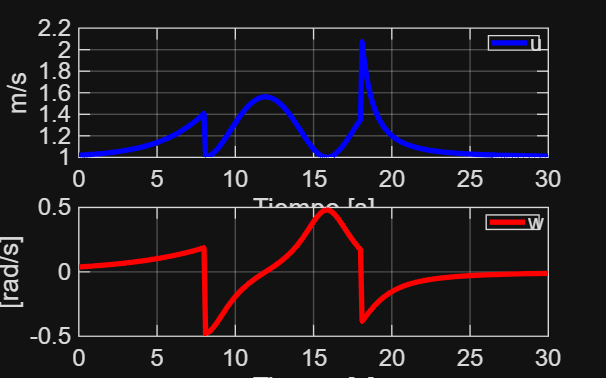


%%%%%%%%%%%%%%%%%%%%%%%%%%%%% GRAFICAS %%%%%%%%%%%%%%%%%%%%%%%%%%%%

graph=figure;
set(graph,'position',sizeScreen);

subplot(211)
plot(t,u,'b','LineWidth',2),grid on
xlabel('Tiempo [s]'),ylabel('m/s'),legend('u')

subplot(212)
plot(t,w,'r','LineWidth',2),grid on
xlabel('Tiempo [s]'),ylabel('[rad/s]'),legend('w')